clear;
load('abalone_dataset.mat');

% Extract age (target variable)
age = data(:, end);

data(isnan(data)) = 0;
% Convert numeric features to a matrix (4 features per sample)
X = data(:, 1:end-1)';

% Normalize features (zero mean, unit variance scaled by 1/sqrt(8))
X = (1/sqrt(8))*((X - mean(X, 2)) ./ std(X, 0, 2));

% Split into training (80%) and test (20%) sets
numSamples = size(X, 2);
rng(1);  % For reproducibility
cv = cvpartition(numSamples, 'HoldOut', 0.2);

XTrainFull = X(:, training(cv));   % Training features before validation split
YTrainFull = age(training(cv));      % Training labels before validation split
XTest  = X(:, test(cv));             % Unseen test features
YTest  = age(test(cv));              % Unseen test labels

% Further split training data into training (80%) and validation (20%)
numTrainSamples = size(XTrainFull, 2);
cvVal = cvpartition(numTrainSamples, 'HoldOut', 0.2);

XTrain = XTrainFull(:, training(cvVal));
YTrain = YTrainFull(training(cvVal));
XVal = XTrainFull(:, test(cvVal));
YVal = YTrainFull(test(cvVal));

% --- Normalize outputs (age) using training statistics ---
YTrainMean = mean(YTrain);
YTrainStd = std(YTrain);

% Normalize training and validation targets
YTrainNorm = (YTrain - YTrainMean) / YTrainStd;
YValNorm   = (YVal - YTrainMean) / YTrainStd;

% Define network layers
layers = [
    featureInputLayer(size(XTrain, 1))
    fullyConnectedLayer(16e3, 'WeightLearnRateFactor', 0, ...
        'WeightsInitializer', @customWeights1, 'BiasL2Factor', 0, 'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(16e3, 'WeightLearnRateFactor', 0, ...
        'WeightsInitializer', @customWeights2, 'BiasL2Factor', 0, 'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(1, 'Name', 'output', ...
        'WeightLearnRateFactor', 0, ...
        'WeightsInitializer', @customWeights3, 'BiasL2Factor', 0, 'BiasInitializer','zeros')
];

% Create deep learning network
net = dlnetwork(layers);

% Convert training and validation data to dlarray
XTrain_dl = dlarray(single(XTrain), "CB");  % 'C' = Channels, 'B' = Batch
XVal_dl = dlarray(single(XVal), "CB");

% Training options with validation data (note that we use normalized outputs)
options = trainingOptions('adam', ...
    'MaxEpochs', 10000, ...
    'Metrics', ["rmse"], ...
    'MiniBatchSize', 4177, ...
    'InitialLearnRate', 0.01, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal_dl, YValNorm}, ...
    'Plots', "training-progress", ...
    'Verbose', 0, 'ValidationFrequency', 10);


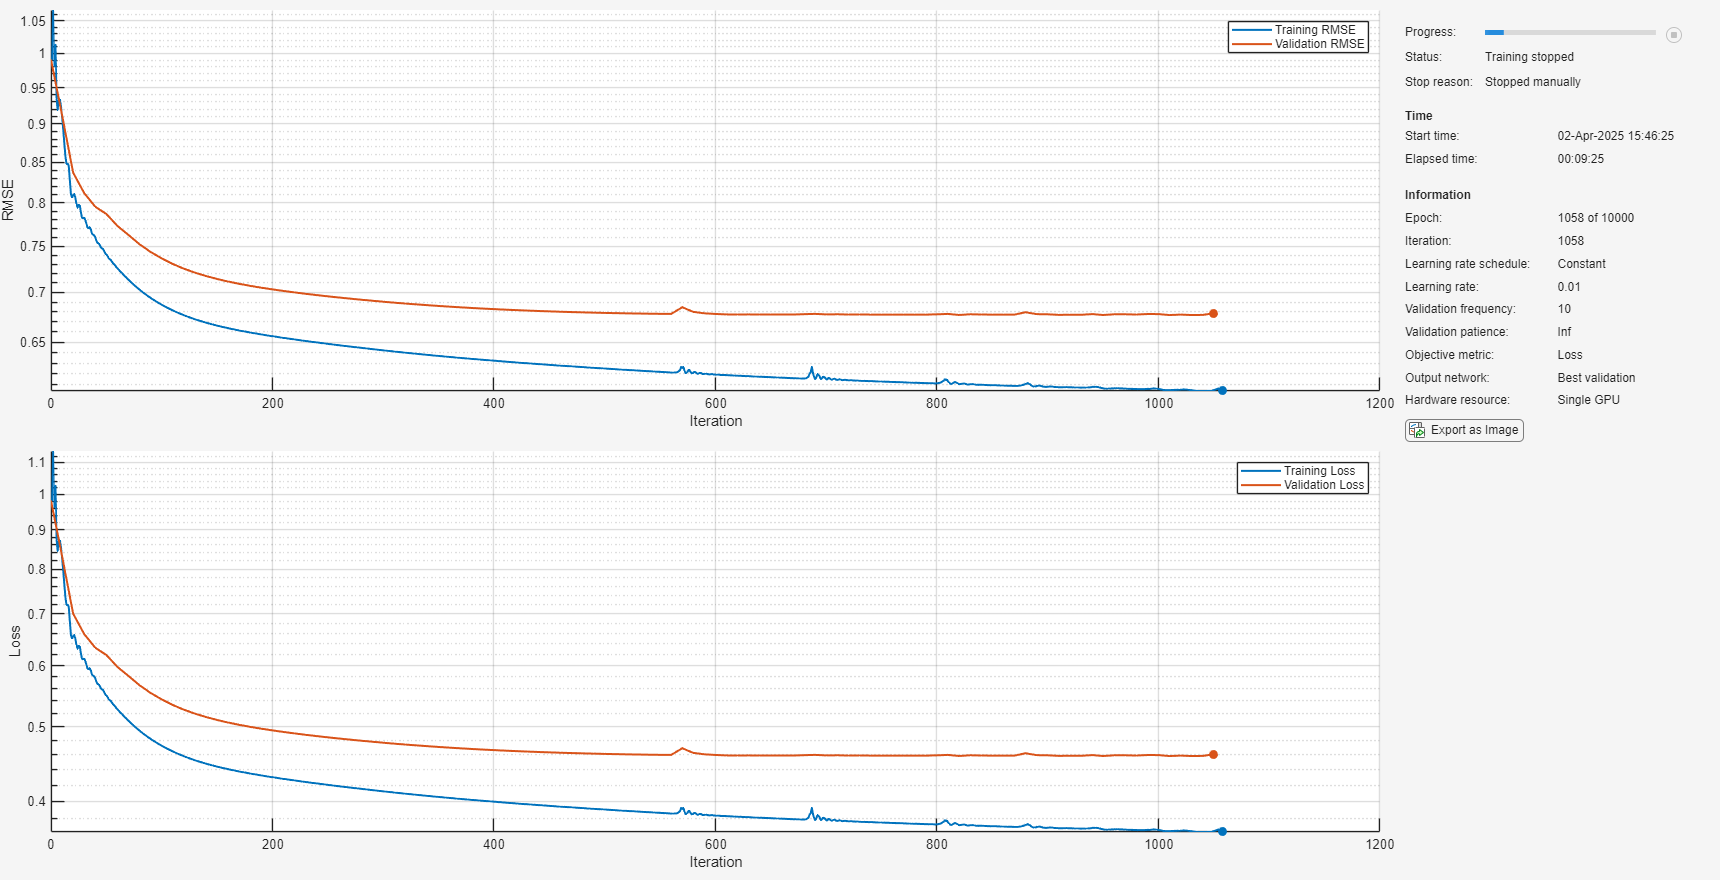

% Train network using normalized training targets
[net,tr] = trainnet(XTrain_dl, YTrainNorm, net, 'mse', options);

% Convert test data to dlarray
XTest_dl = dlarray(single(XTest), "CB");

% Predict normalized outputs
YpredNorm = predict(net, XTest_dl);

% Scale predictions back to original units
Ypred = YpredNorm * YTrainStd + YTrainMean;

% Compute and display mean absolute error on the original scale
meanError = mean(abs(Ypred - YTest'));
disp(meanError);

  1(C) × 1(B) single dlarray

    1.4868

